# Fórmulas de derivación numérica

**Equipo Alfa Dinamita:**

Israel Cabrera Portilla (188517)

Lorena Patricia Barrera Rodríguez (164694)

Andrea Carolina Padilla Rodríguez (166605)

## Introducción

En esta sección se expone el contexto del problema que se desea solucionar, así como  el objetivo a cumplir.  Además,  se  describe  la  organización  del  presente documento.

### Contexto

En computación (y matemáticas), el concepto de «error numérico» es el error en los cálculos numéricos realizados por la computadora. Esto puede suceder debido a dos factores [1]: 

- Error de redondeo: ocurre porque las computadoras usan un número definido de bits para representar números. Entonces, al realizar un cálculo numérico, en cada paso se introducen errores de redondeo; aunque un error de redondeo individual puede ser pequeño, el efecto acumulativo puede resultar significativo. Ciertos tipos de manipulaciones matemáticas son más susceptible al error de redondeo que otras, como la cancelación sustractiva, productos internos, el aumento en el número de cálculos en un análisis, entre otros.

- Error de truncamiento: se refiere a la diferencia entre la solución matemática exacta y la solución aproximada generada cuando se simplifican las ecuaciones matemáticas para facilitar su cálculo; estas simplificaciones implican el truncamiento de una expansión en serie infinita para hacer posible y práctico el cálculo, o porque se desechan los bits menos significativos de una operación aritmética.

Entonces, el error numérico total es la suma de los errores de truncamiento y redondeo [2]. Aunque agregar dígitos significativos puede mejorar la aproximación, tales cantidades siempre tendrán algún error de redondeo cuando se almacenen en una computadora. Por su parte, el error de truncamiento se puede reducir disminuyendo el tamaño del paso. Debido a que una disminución en el tamaño del paso puede conducir a una cancelación sustractiva o a un aumento en los cálculos, los errores de truncamiento disminuyen a medida que aumentan los errores de redondeo.

### Identificación del problema

De forma predeterminada, MATLAB ha adoptado el formato de doble precisión IEEE Standard 754 en el que se utilizan ocho bytes (64 bits) para representar números de punto flotante: $x={\left(-1\right)}^s *\left(2^{e-1023} \right)*\left(1\ldotp f\right)$ [3], en donde el signo está determinado por un bit de signo, la mantisa $f$ está determinada por un número binario de 52 bits, y el exponente $e$ está determinado por un número binario de 11 bits, del cual se resta 1023 para obtener $e$.

### Objetivo general

Explorar los errores que presentan diferentes fórmulas de derivación numérica: las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada, $O\left(h\right)$ y $O\left(h^2 \right)$. 

### Organización del documento

El documento está estructurado de la siguiente manera:

- **Sección 1: Introducción**. Se describe el contexto, el problema a resolver y el objetivo general del proyecto.

- **Sección 2: Análisis**. Se especifican los requerimientos funcionales y no funcionales de la solución, así como sus restricciones.

- **Sección 3: Desarrollo**. Se exponen detalladamente las funciones desarrolladas que pretenden cumplir con el objetivo del proyecto (esta sección corresponde a Anexo: Funciones).

- **Sección 4: Pruebas y Resultados**. Se presentan las pruebas llevadas a cabo con el fin de evaluar el cumplimiento de los requerimientos y explorar los errores obtenidos de las funciones de aproximación.

- **Sección 5: Conclusiones**. Se evalúa el desempeño general del proyecto en relación con  el  objetivo  y  el  problema  a  resolver.  Además,  se  explican  posibles  mejoras  y propuestas de trabajos futuros para profundizar la solución.

## Análisis

En esta sección se describen las funcionalidades generales que debe cumplir la solución, así como las restricciones para su desarrollo.

### Requerimientos

#### Funcionales

- a ver digan otros 2 o 3 pls

- El sistema debe mostrar recursos gráficos para facilitar la evaluación de los errores.

#### No funcionales

- En caso de error, se debe informar al usuario de manera clara cuál fue dicho error.

- El código debe ser documentado adecuadamente siguiendo las convenciones de código (nombres de variables y funciones, sangría y espaciado, etc.)

### Restricciones

- supongo que aqui podriamos poner algo de qué funciones usaremos o no c

## Pruebas y resultados

En esta sección se muestran las pruebas realizadas para determinar la eficiencia de los algoritmos de aproximación dependiendo de la` h `utilizada para calcular las derivadas. También, se muestran los errores obtenidos de las aproximaciones y su gráfica correspondiente.

Para probar los métodos, se utilizaron aribitrariamente las siguientes funciones y puntos:

- $f\left(x\right)=-0\ldotp 1x^4 -0\ldotp 15x^3 -0\ldotp 5x^2 -0\ldotp 25x+1\ldotp 2$    ;   ` x = 0.5`

- $f\left(x\right)=\frac{\sin \left(x^2 \right)}{x^2 }$    ;   ` x = 2.5`

- $f\left(x\right)=2x+6$    ;   ` x = 1.75`

- $f\left(x\right)=\frac{7}{29}$    ;   ` x = 4`

- $f\left(\right)=2x^3 -\frac{\sqrt{\Pi }}{x}+2$    ;   ` x = 1`

### Aproximaciones de la función $f\left(x\right)=-0\ldotp 1x^4 -0\ldotp 15x^3 -0\ldotp 5x^2 -0\ldotp 25x+1\ldotp 2$ con `x = 0.5`

f = @(x) -0.1 * x.^4 - 0.15 * x.^3 - 0.5 * x.^2 - 0.25 * x + 1.2;
x = 0.5;

#### Primera derivada

df = matlabFunction(diff(sym(f)));
dfx = df(x)

dfx = -0.9125

El valor real de la primera derivada de la función en el punto` x `es `-0.9125`. 

**Aproximaciones hacia adelante de primer y segundo orden:**

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -2.23750000000000 	  1.3250000000000
  0.1000000000 	 -1.00360000000000 	  0.0911000000000
  0.0100000000 	 -0.92128509999999 	  0.0087851000000
  0.0010000000 	 -0.91337535009994 	  0.0008753500999
  0.0001000000 	 -0.91258750349987 	  0.0000875034999
  0.0000100000 	 -0.91250875002835 	  0.0000087500284
  0.0000010000 	 -0.91250087497219 	  0.0000008749722
  0.0000001000 	 -0.91250008660282 	  0.0000000866028
  0.0000000100 	 -0.91250000888721 	  0.0000000088872
  0.0000000010 	 -0.91249996447829 	  0.0000000355217
  0.0000000001 	 -0.91250007550059 	  0.0000000755006


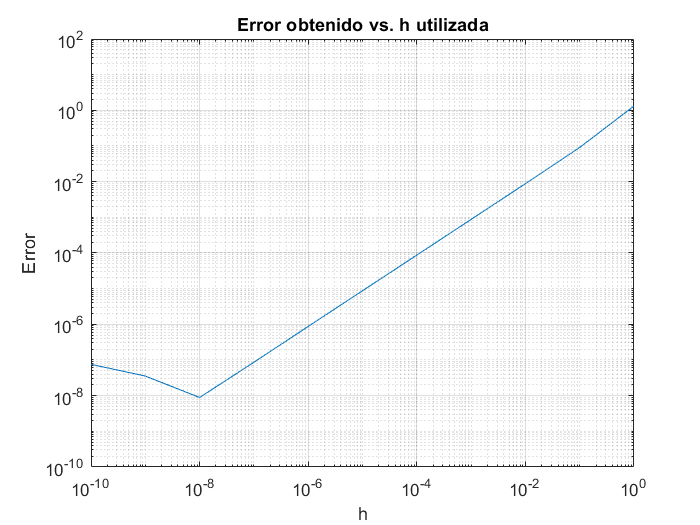

dfForward1(f, x);

Primera derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.38750000000000 	  1.3000000000000
  0.1000000000 	 -0.90490000000000 	  0.0076000000000
  0.0100000000 	 -0.91242939999998 	  0.0000706000000
  0.0010000000 	 -0.91249929939985 	  0.0000007006002
  0.0001000000 	 -0.91249999299992 	  0.0000000070001
  0.0000100000 	 -0.91249999991660 	  0.0000000000834
  0.0000010000 	 -0.91250000000542 	  0.0000000000054
  0.0000001000 	 -0.91249999778498 	  0.0000000022150
  0.0000000100 	 -0.91250000888721 	  0.0000000088872
  0.0000000010 	 -0.91250007550059 	  0.0000000755006
  0.0000000001 	 -0.91250118572361 	  0.0000011857236


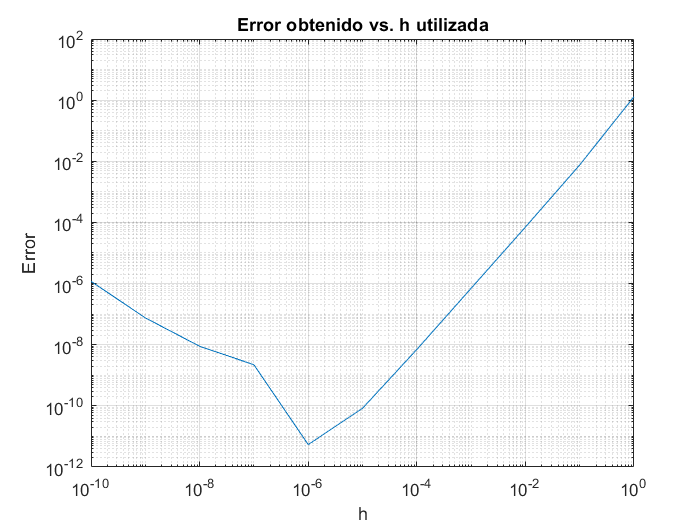

dfForward2(f, x);

**Aproximación centrada de segundo orden:**

Primera derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -1.26250000000000 	  0.3500000000000
  0.1000000000 	 -0.91600000000000 	  0.0035000000000
  0.0100000000 	 -0.91253500000000 	  0.0000350000000
  0.0010000000 	 -0.91250035000001 	  0.0000003500000
  0.0001000000 	 -0.91250000349985 	  0.0000000034998
  0.0000100000 	 -0.91250000003318 	  0.0000000000332
  0.0000010000 	 -0.91250000000542 	  0.0000000000054
  0.0000001000 	 -0.91249999945031 	  0.0000000005497
  0.0000000100 	 -0.91250000333609 	  0.0000000033361
  0.0000000010 	 -0.91250001998944 	  0.0000000199894
  0.0000000001 	 -0.91250007550059 	  0.0000000755006


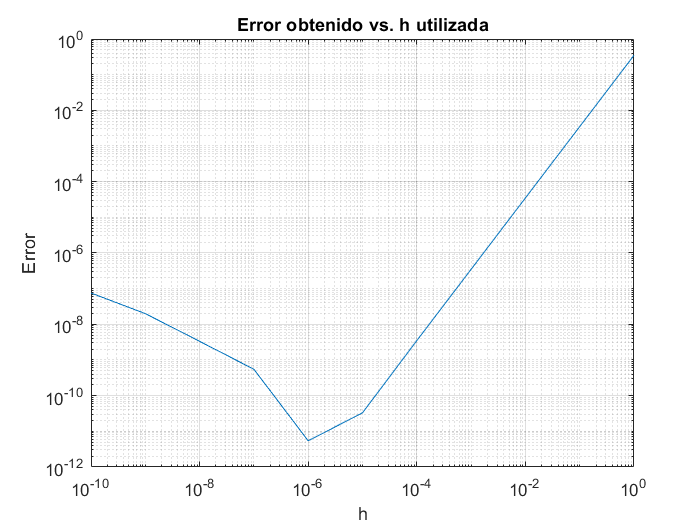

dfCentral(f, x);

**Aproximaciones hacia atrás de primer y segundo orden:**

Primera derivada: Aproximación hacia atrás O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.28750000000000 	  0.6250000000000
  0.1000000000 	 -0.82840000000000 	  0.0841000000000
  0.0100000000 	 -0.90378490000000 	  0.0087151000000
  0.0010000000 	 -0.91162534990008 	  0.0008746500999
  0.0001000000 	 -0.91241250349983 	  0.0000874965002
  0.0000100000 	 -0.91249125003801 	  0.0000087499620
  0.0000010000 	 -0.91249912503866 	  0.0000008749613
  0.0000001000 	 -0.91249991229780 	  0.0000000877022
  0.0000000100 	 -0.91249999778498 	  0.0000000022150
  0.0000000010 	 -0.91250007550059 	  0.0000000755006
  0.0000000001 	 -0.91250007550059 	  0.0000000755006


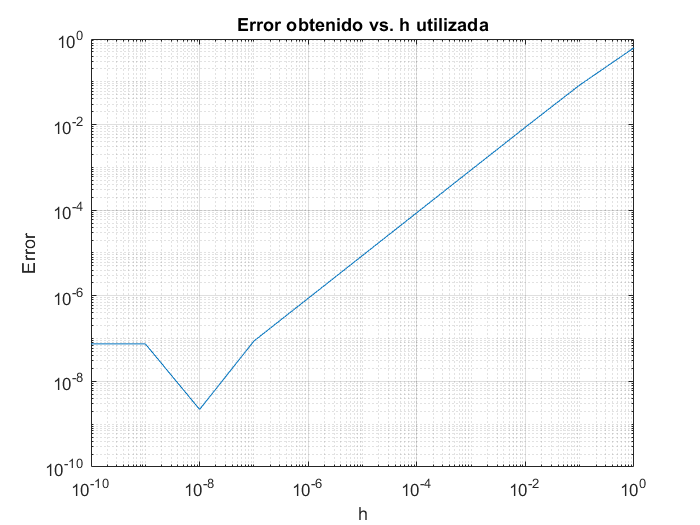

dfBackward1(f, x);

Primera derivada: Aproximación hacia atrás O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.81250000000000 	  0.1000000000000
  0.1000000000 	 -0.90610000000000 	  0.0064000000000
  0.0100000000 	 -0.91243060000000 	  0.0000694000000
  0.0010000000 	 -0.91249930060011 	  0.0000006993999
  0.0001000000 	 -0.91249999299992 	  0.0000000070001
  0.0000100000 	 -0.91249999992771 	  0.0000000000723
  0.0000010000 	 -0.91250000000542 	  0.0000000000054
  0.0000001000 	 -0.91249999889520 	  0.0000000011048
  0.0000000100 	 -0.91250000888721 	  0.0000000088872
  0.0000000010 	 -0.91250007550059 	  0.0000000755006
  0.0000000001 	 -0.91249952038908 	  0.0000004796109


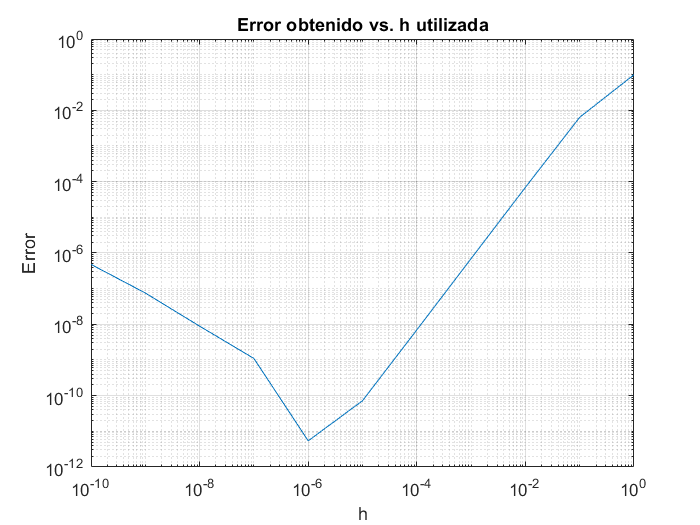

dfBackward2(f, x);

#### Segunda derivada

ddf = matlabFunction(diff(diff(sym(f))));
ddfx = ddf(x)

ddfx = -1.7500

El valor real de la segunda derivada de la función en el punto` x `es `-1.75`.

**Aproximaciones hacia adelante de primer y segundo orden:**

Segunda derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -5.25000000000000 	  3.5000000000000
  0.1000000000 	 -1.97400000000002 	  0.2240000000000
  0.0100000000 	 -1.77114000000200 	  0.0211400000020
  0.0010000000 	 -1.75210140007653 	  0.0021014000765
  0.0001000000 	 -1.75021001025399 	  0.0002100102540
  0.0000100000 	 -1.75002234925614 	  0.0000223492561
  0.0000010000 	 -1.75004455371663 	  0.0000445537166
  0.0000001000 	 -1.76525460915400 	  0.0152546091540
  0.0000000100 	 -1.11022302462516 	  0.6397769753748
  0.0000000010 	 -111.02230246251560 	 109.2723024625156
  0.0000000001 	 0.00000000000000 	  1.7500000000000


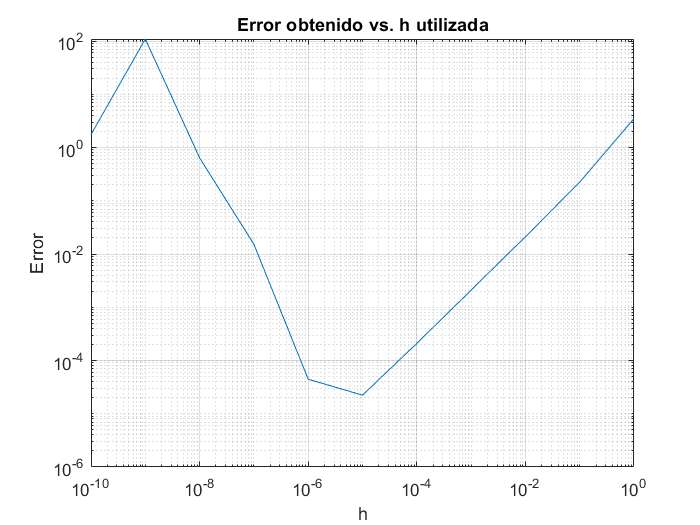

ddfForward1(f, x);

Segunda derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.45000000000000 	  2.2000000000000
  0.1000000000 	 -1.72800000000011 	  0.0219999999999
  0.0100000000 	 -1.74978000000214 	  0.0002199999979
  0.0010000000 	 -1.74999779978258 	  0.0000022002174
  0.0001000000 	 -1.75000003377335 	  0.0000000337733
  0.0000100000 	 -1.75000236524170 	  0.0000023652417
  0.0000010000 	 -1.75037762062402 	  0.0003776206240
  0.0000001000 	 -1.75415237890775 	  0.0041523789077
  0.0000000100 	 2.22044604925031 	  3.9704460492503
  0.0000000010 	 -666.13381477509358 	 664.3838147750936
  0.0000000001 	 -22204.46049250311989 	 22202.7104925031199


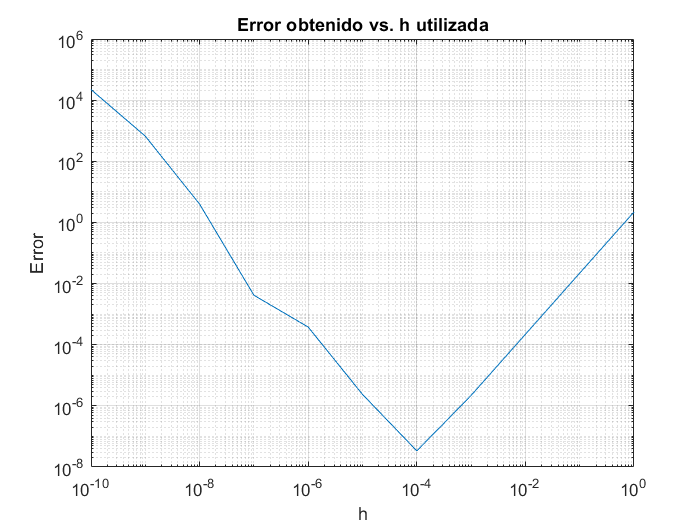

ddfForward2(f, x);

**Aproximación centrada de segundo orden:**

Segunda derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -1.95000000000000 	  0.2000000000000
  0.1000000000 	 -1.75200000000000 	  0.0020000000000
  0.0100000000 	 -1.75001999999869 	  0.0000199999987
  0.0010000000 	 -1.75000019986271 	  0.0000001998627
  0.0001000000 	 -1.75000000046666 	  0.0000000004667
  0.0000100000 	 -1.74999903457262 	  0.0000009654274
  0.0000010000 	 -1.74993353141417 	  0.0000664685858
  0.0000001000 	 -1.74305014866149 	  0.0069498513385
  0.0000000100 	 -1.11022302462516 	  0.6397769753748
  0.0000000010 	 111.02230246251560 	 112.7723024625156
  0.0000000001 	 0.00000000000000 	  1.7500000000000


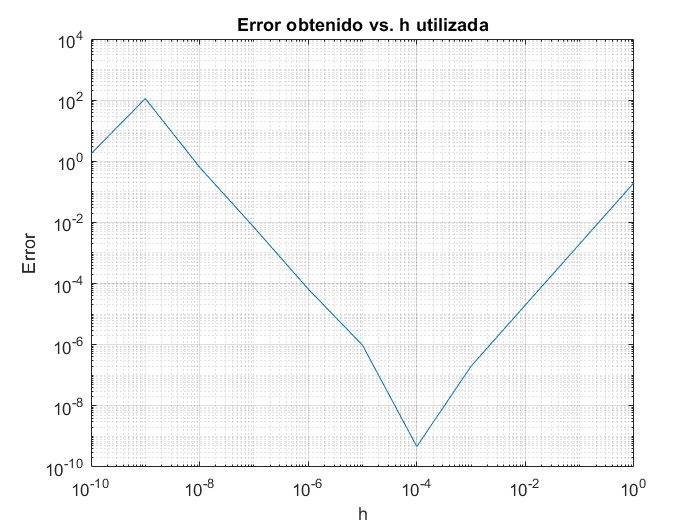

ddfCentral(f, x);

### Aproximaciones de la función $f\left(x\right)=\frac{\sin \left(x^2 \right)}{x^2 }$ con `x = 2.5`

f = @(x) sin(x.^2) ./ x.^2;
x = 2.5;

#### Primera derivada

df = matlabFunction(diff(sym(f)));
dfx = df(x)

dfx = 0.8038

El valor real de la primera derivada de la función en el punto` x `es 0.8038. 

**Aproximaciones hacia adelante de primer y segundo orden:**

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.02008882371820 	  0.8238952980159
  0.1000000000 	 0.73200906360285 	  0.0717974106948
  0.0100000000 	 0.79933758846928 	  0.0044688858284
  0.0010000000 	 0.80338744843924 	  0.0004190258584
  0.0001000000 	 0.80376485074704 	  0.0000416235507
  0.0000100000 	 0.80380231473132 	  0.0000041595664
  0.0000010000 	 0.80380605849573 	  0.0000004158020
  0.0000001000 	 0.80380643173623 	  0.0000000425615
  0.0000000100 	 0.80380646366382 	  0.0000000106339
  0.0000000010 	 0.80380654042533 	  0.0000000661276
  0.0000000001 	 0.80380653522116 	  0.0000000609235


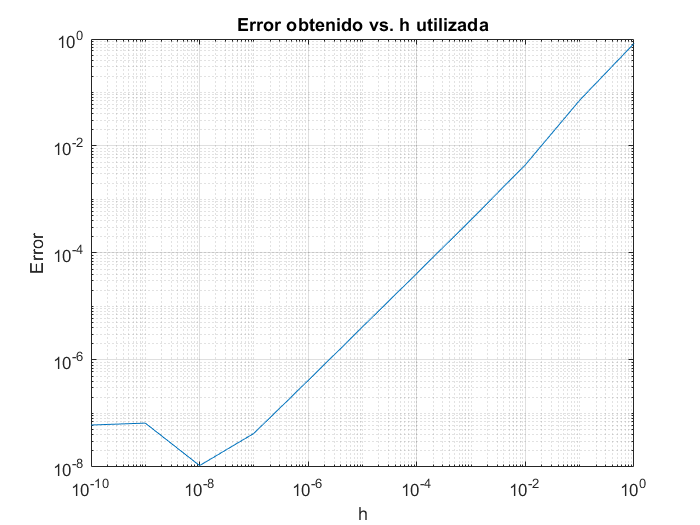

dfForward1(f, x);

Primera derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.06716593813218 	  0.8709724124299
  0.1000000000 	 0.85782220824940 	  0.0540157339517
  0.0100000000 	 0.80442362472642 	  0.0006171504287
  0.0010000000 	 0.80381267341445 	  0.0000061991168
  0.0001000000 	 0.80380653631622 	  0.0000000620185
  0.0000100000 	 0.80380647490882 	  0.0000000006111
  0.0000010000 	 0.80380647463074 	  0.0000000003331
  0.0000001000 	 0.80380647155681 	  0.0000000027409
  0.0000000100 	 0.80380646947514 	  0.0000000048225
  0.0000000010 	 0.80380654216006 	  0.0000000678624
  0.0000000001 	 0.80380653522116 	  0.0000000609235


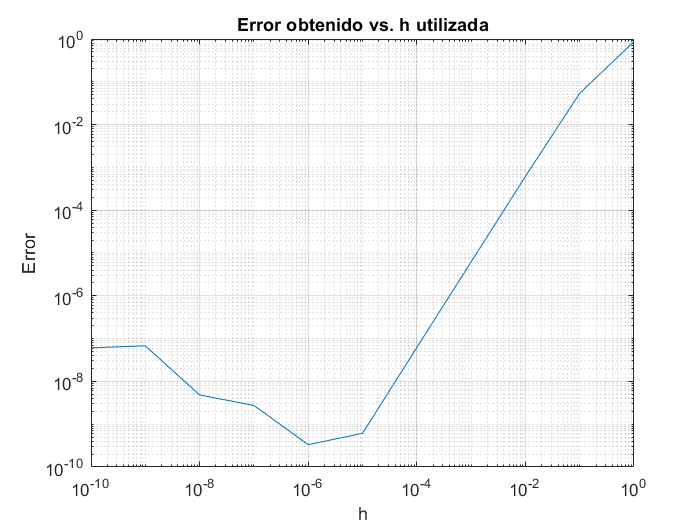

dfForward2(f, x);

**Aproximación centrada de segundo orden:**

Primera derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.18560390404689 	  0.9894103783446
  0.1000000000 	 0.77317807099125 	  0.0306284033064
  0.0100000000 	 0.80349643015883 	  0.0003100441389
  0.0010000000 	 0.80380337347806 	  0.0000031008196
  0.0001000000 	 0.80380644329115 	  0.0000000310065
  0.0000100000 	 0.80380647399284 	  0.0000000003048
  0.0000010000 	 0.80380647440653 	  0.0000000001088
  0.0000001000 	 0.80380647298362 	  0.0000000013141
  0.0000000100 	 0.80380646938841 	  0.0000000049093
  0.0000000010 	 0.80380654085901 	  0.0000000665613
  0.0000000001 	 0.80380653522116 	  0.0000000609235


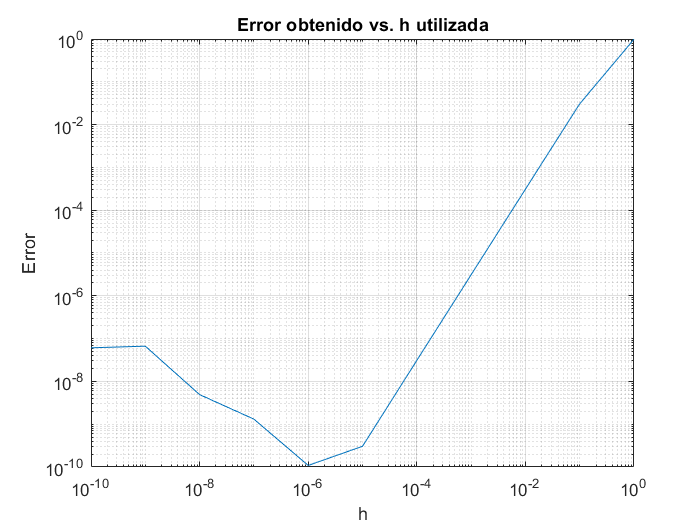

dfCentral(f, x);

**Aproximaciones hacia atrás de primer y segundo orden:**

Primera derivada: Aproximación hacia atrás O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.35111898437557 	  1.1549254586733
  0.1000000000 	 0.81434707837964 	  0.0105406040820
  0.0100000000 	 0.80765527184838 	  0.0038487975507
  0.0010000000 	 0.80421929851687 	  0.0004128242192
  0.0001000000 	 0.80384803583527 	  0.0000415615376
  0.0000100000 	 0.80381063325436 	  0.0000041589567
  0.0000010000 	 0.80380689031732 	  0.0000004160196
  0.0000001000 	 0.80380651423101 	  0.0000000399333
  0.0000000100 	 0.80380647511299 	  0.0000000008153
  0.0000000010 	 0.80380654129270 	  0.0000000669950
  0.0000000001 	 0.80380653522116 	  0.0000000609235


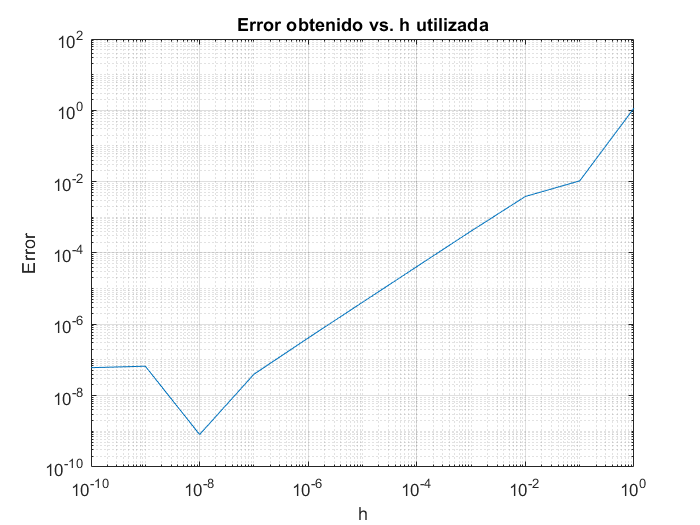

dfBackward1(f, x);

Primera derivada: Aproximación hacia atrás O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.20477571291830 	  1.0085821872160
  0.1000000000 	 0.86339492114563 	  0.0595884468479
  0.0100000000 	 0.80442858389533 	  0.0006221095976
  0.0010000000 	 0.80381267836724 	  0.0000062040696
  0.0001000000 	 0.80380653631904 	  0.0000000620214
  0.0000100000 	 0.80380647493731 	  0.0000000006396
  0.0000010000 	 0.80380647455745 	  0.0000000002598
  0.0000001000 	 0.80380647084124 	  0.0000000034564
  0.0000000100 	 0.80380646925830 	  0.0000000050394
  0.0000000010 	 0.80380654042533 	  0.0000000661276
  0.0000000001 	 0.80380652654755 	  0.0000000522499


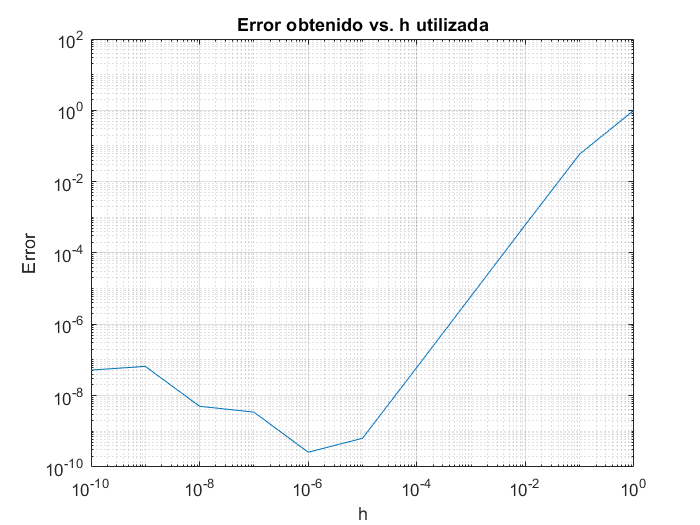

dfBackward2(f, x);

#### Segunda derivada

ddf = matlabFunction(diff(diff(sym(f))));
ddfx = ddf(x)

ddfx = -0.8319

El valor real de la segunda derivada de la función en el punto` x `es `-0.8319`.

**Aproximaciones hacia adelante de primer y segundo orden:**

Segunda derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.09415422882796 	  0.9260051317950
  0.1000000000 	 -2.51626289293102 	  1.6844119899640
  0.0100000000 	 -1.01720725142937 	  0.1853563484624
  0.0010000000 	 -0.85044995041215 	  0.0185990474452
  0.0001000000 	 -0.83371138395738 	  0.0018604809904
  0.0000100000 	 -0.83203549952615 	  0.0001845965592
  0.0000010000 	 -0.83226914943113 	  0.0004182464641
  0.0000001000 	 -0.79649828399475 	  0.0353526189722
  0.0000000100 	 -1.16226472890446 	  0.3304138259375
  0.0000000010 	 -1.73472347597681 	  0.9028725730098
  0.0000000001 	 173.47234759768062 	 174.3041985006476


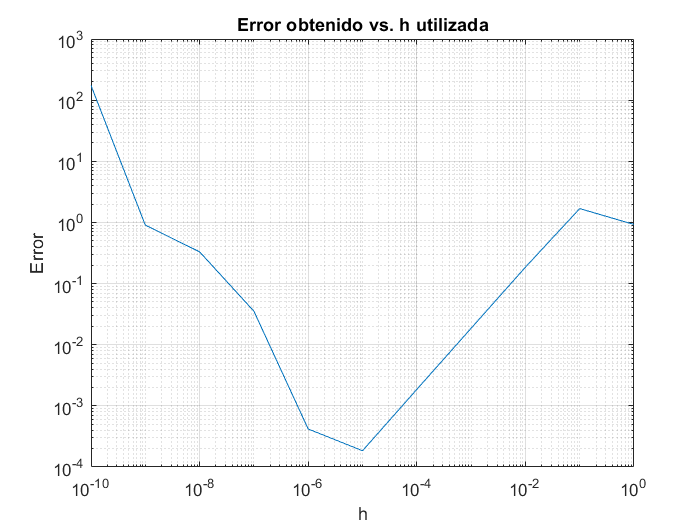

ddfForward1(f, x);

Segunda derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.34142701559901 	  1.1732779185660
  0.1000000000 	 -1.38950246702154 	  0.5576515640545
  0.0100000000 	 -0.83322214600959 	  0.0013712430426
  0.0010000000 	 -0.83186044200559 	  0.0000095390386
  0.0001000000 	 -0.83185112478845 	  0.0000002218215
  0.0000100000 	 -0.83184660548685 	  0.0000042974801
  0.0000010000 	 -0.83310441878481 	  0.0012535158178
  0.0000001000 	 -0.71088968045530 	  0.1209612225117
  0.0000000100 	 -2.60208521396521 	  1.7702343109982
  0.0000000010 	 281.02520310824264 	 281.8570540112096
  0.0000000001 	 693.88939039072250 	 694.7212412936894


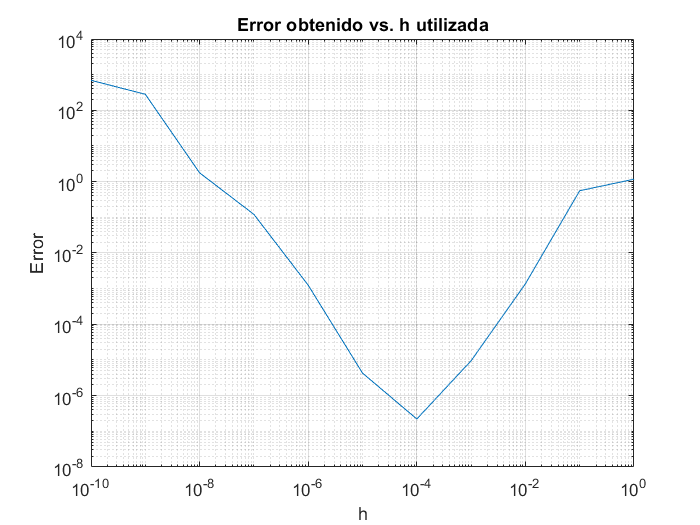

ddfForward2(f, x);

**Aproximación centrada de segundo orden:**

Segunda derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.33103016065738 	  1.1628810636244
  0.1000000000 	 -0.82338014776790 	  0.0084707551991
  0.0100000000 	 -0.83176833791039 	  0.0000825650566
  0.0010000000 	 -0.83185007763130 	  0.0000008253357
  0.0001000000 	 -0.83185088236085 	  0.0000000206062
  0.0000100000 	 -0.83185230405347 	  0.0000014010865
  0.0000010000 	 -0.83182159077433 	  0.0000293121927
  0.0000001000 	 -0.82494774900077 	  0.0069031539662
  0.0000000100 	 -1.14491749414469 	  0.3130665911777
  0.0000000010 	 -0.86736173798840 	  0.0355108350214
  0.0000000001 	 0.00000000000000 	  0.8318509029670


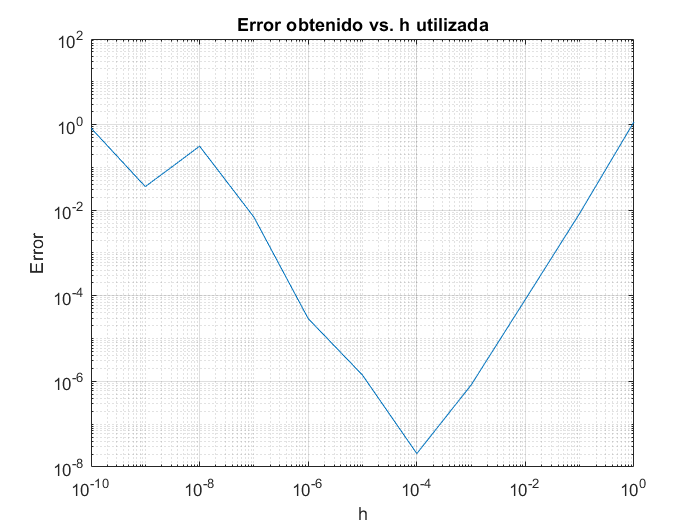

ddfCentral(f, x);

### Aproximaciones de la función $f\left(x\right)=2x+6$ con `x = 1.75`

f = @(x) 2 * x + 6;
x = 1.75;

#### Primera derivada

En este caso, la primera derivada de la función es una constante:

df = matlabFunction(diff(sym(f)))

df = function_handle with value:
    @()2.0


**Aproximaciones hacia adelante de primer y segundo orden:**

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 2.00000000000000 	  0.0000000000000
  0.1000000000 	 1.99999999999999 	  0.0000000000000
  0.0100000000 	 1.99999999999996 	  0.0000000000000
  0.0010000000 	 1.99999999999889 	  0.0000000000011
  0.0001000000 	 1.99999999999534 	  0.0000000000047
  0.0000100000 	 1.99999999992428 	  0.0000000000757
  0.0000010000 	 2.00000000027956 	  0.0000000002796
  0.0000001000 	 2.00000000560863 	  0.0000000056086
  0.0000000100 	 1.99999998784506 	  0.0000000121549
  0.0000000010 	 2.00000016548074 	  0.0000001654807
  0.0000000001 	 2.00000016548074 	  0.0000001654807


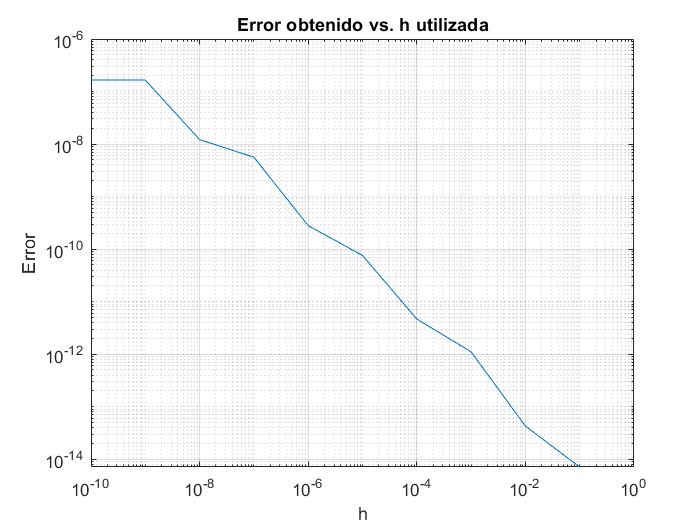

dfForward1(f, x);

Primera derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 2.00000000000000 	  0.0000000000000
  0.1000000000 	 1.99999999999999 	  0.0000000000000
  0.0100000000 	 1.99999999999996 	  0.0000000000000
  0.0010000000 	 1.99999999999889 	  0.0000000000011
  0.0001000000 	 1.99999999999534 	  0.0000000000047
  0.0000100000 	 1.99999999992428 	  0.0000000000757
  0.0000010000 	 2.00000000027956 	  0.0000000002796
  0.0000001000 	 2.00000002337219 	  0.0000000233722
  0.0000000100 	 1.99999998784506 	  0.0000000121549
  0.0000000010 	 2.00000016548074 	  0.0000001654807
  0.0000000001 	 2.00000016548074 	  0.0000001654807


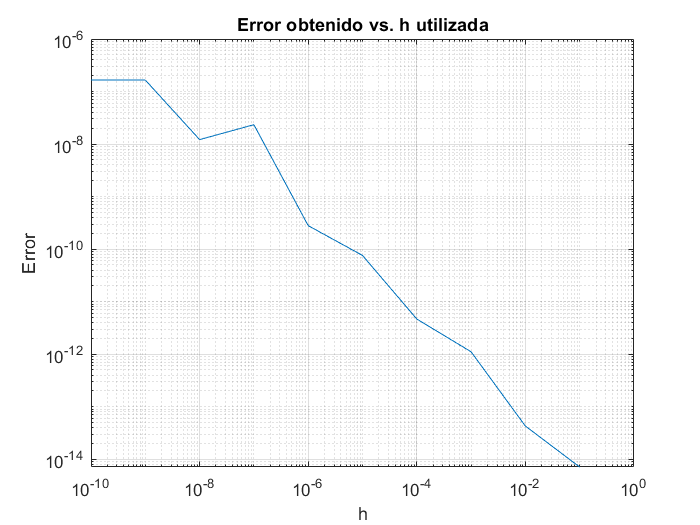

dfForward2(f, x);

**Aproximación centrada de segundo orden:**

Primera derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 2.00000000000000 	  0.0000000000000
  0.1000000000 	 1.99999999999999 	  0.0000000000000
  0.0100000000 	 1.99999999999996 	  0.0000000000000
  0.0010000000 	 1.99999999999889 	  0.0000000000011
  0.0001000000 	 1.99999999999534 	  0.0000000000047
  0.0000100000 	 1.99999999992428 	  0.0000000000757
  0.0000010000 	 2.00000000027956 	  0.0000000002796
  0.0000001000 	 2.00000000560863 	  0.0000000056086
  0.0000000100 	 1.99999998784506 	  0.0000000121549
  0.0000000010 	 2.00000016548074 	  0.0000001654807
  0.0000000001 	 2.00000016548074 	  0.0000001654807


dfCentral(f, x);

**Aproximaciones hacia atrás de primer y segundo orden:**

Primera derivada: Aproximación hacia atrás O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 2.00000000000000 	  0.0000000000000
  0.1000000000 	 1.99999999999999 	  0.0000000000000
  0.0100000000 	 1.99999999999996 	  0.0000000000000
  0.0010000000 	 1.99999999999889 	  0.0000000000011
  0.0001000000 	 1.99999999999534 	  0.0000000000047
  0.0000100000 	 1.99999999992428 	  0.0000000000757
  0.0000010000 	 2.00000000027956 	  0.0000000002796
  0.0000001000 	 2.00000000560863 	  0.0000000056086
  0.0000000100 	 1.99999998784506 	  0.0000000121549
  0.0000000010 	 2.00000016548074 	  0.0000001654807
  0.0000000001 	 2.00000016548074 	  0.0000001654807


dfBackward1(f, x);

Primera derivada: Aproximación hacia atrás O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 2.00000000000000 	  0.0000000000000
  0.1000000000 	 1.99999999999998 	  0.0000000000000
  0.0100000000 	 1.99999999999996 	  0.0000000000000
  0.0010000000 	 1.99999999999800 	  0.0000000000020
  0.0001000000 	 1.99999999999534 	  0.0000000000047
  0.0000100000 	 1.99999999983547 	  0.0000000001645
  0.0000010000 	 2.00000000027956 	  0.0000000002796
  0.0000001000 	 2.00000001449041 	  0.0000000144904
  0.0000000100 	 1.99999998784506 	  0.0000000121549
  0.0000000010 	 2.00000016548074 	  0.0000001654807
  0.0000000001 	 2.00000016548074 	  0.0000001654807


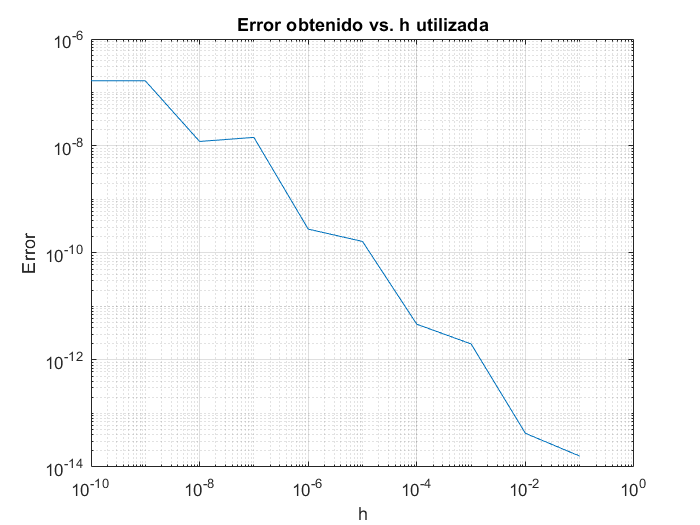

dfBackward2(f, x);

#### Segunda derivada

Como el resultado de la primera derivada de la función es una constante, la segunda derivada es` 0:`

ddf = matlabFunction(diff(diff(sym(f))))

ddf = function_handle with value:
    @()0.0


**Aproximaciones hacia adelante de primer y segundo orden:**

Segunda derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000018 	  0.0000000000002
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000177636 	  0.0000000017764
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00001776356839 	  0.0000177635684
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 -0.17763568394002 	  0.1776356839400
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


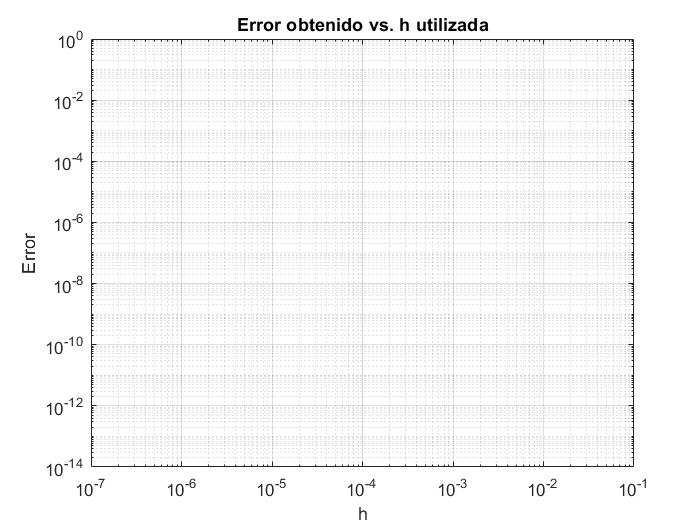

ddfForward1(f, x);

Segunda derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000710543 	  0.0000000071054
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00007105427358 	  0.0000710542736
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 -0.71054273576010 	  0.7105427357601
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 -355271.36788004991831 	 355271.3678800499183


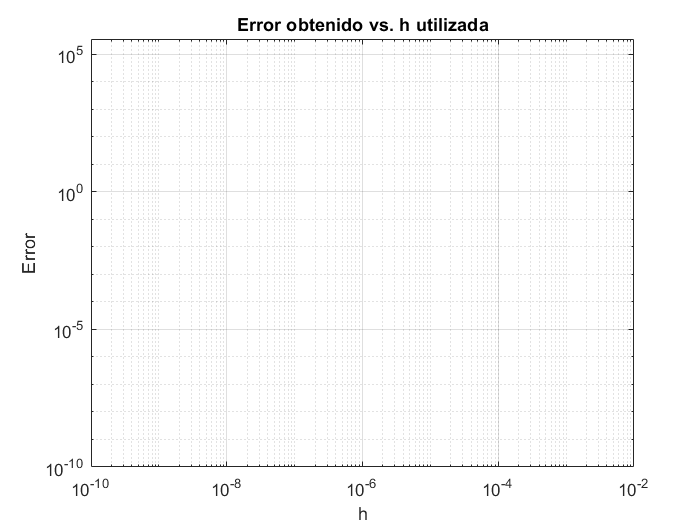

ddfForward2(f, x);

**Aproximación centrada de segundo orden:**

Segunda derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 0.00000000000000 	  0.0000000000000
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


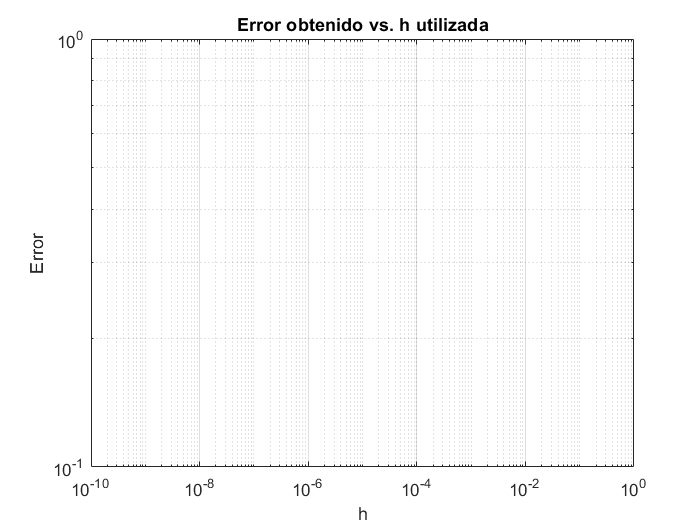

ddfCentral(f, x);

### Aproximaciones de la función $f\left(x\right)=\frac{7}{29}$ con `x = 4`

f = @(x) 7 / 29;
x = 4;

#### Primera derivada

En este caso, como la función es únicamente una constante, su primera derivada es` 0`:

df = matlabFunction(diff(sym(f)))

df = function_handle with value:
    @()0.0


**Aproximaciones hacia adelante de primer y segundo orden:**

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 0.00000000000000 	  0.0000000000000
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


dfForward1(f, x);

Primera derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 0.00000000000000 	  0.0000000000000
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


dfForward2(f, x);

**Aproximación centrada de segundo orden:**

Primera derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 0.00000000000000 	  0.0000000000000
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


dfCentral(f, x);

**Aproximaciones hacia atrás de primer y segundo orden:**

Primera derivada: Aproximación hacia atrás O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 0.00000000000000 	  0.0000000000000
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


dfBackward1(f, x);

Primera derivada: Aproximación hacia atrás O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.00000000000000 	  0.0000000000000
  0.1000000000 	 -0.00000000000000 	  0.0000000000000
  0.0100000000 	 -0.00000000000000 	  0.0000000000000
  0.0010000000 	 -0.00000000000001 	  0.0000000000000
  0.0001000000 	 -0.00000000000014 	  0.0000000000001
  0.0000100000 	 -0.00000000000139 	  0.0000000000014
  0.0000010000 	 -0.00000000001388 	  0.0000000000139
  0.0000001000 	 -0.00000000013878 	  0.0000000001388
  0.0000000100 	 -0.00000000138778 	  0.0000000013878
  0.0000000010 	 -0.00000001387779 	  0.0000000138778
  0.0000000001 	 -0.00000013877788 	  0.0000001387779


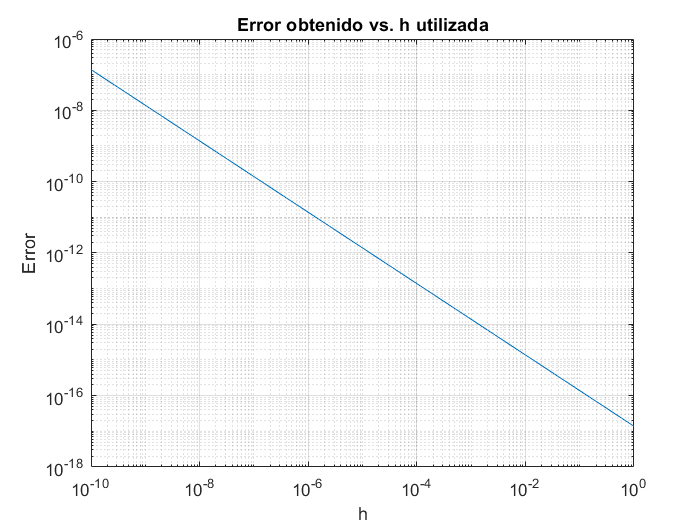

dfBackward2(f, x);

#### Segunda derivada

Como la primera derivada es` 0`, la segunda derivada también es` 0:`

ddf = matlabFunction(diff(diff(sym(f))))

ddf = function_handle with value:
    @()0.0


**Aproximaciones hacia adelante de primer y segundo orden:**

Segunda derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 0.00000000000000 	  0.0000000000000
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


ddfForward1(f, x);

Segunda derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000001 	  0.0000000000000
  0.0100000000 	 0.00000000000056 	  0.0000000000006
  0.0010000000 	 0.00000000005551 	  0.0000000000555
  0.0001000000 	 0.00000000555112 	  0.0000000055511
  0.0000100000 	 0.00000055511151 	  0.0000005551115
  0.0000010000 	 0.00005551115123 	  0.0000555111512
  0.0000001000 	 0.00555111512313 	  0.0055511151231
  0.0000000100 	 0.55511151231258 	  0.5551115123126
  0.0000000010 	 55.51115123125780 	 55.5111512312578
  0.0000000001 	 5551.11512312577997 	 5551.1151231257800


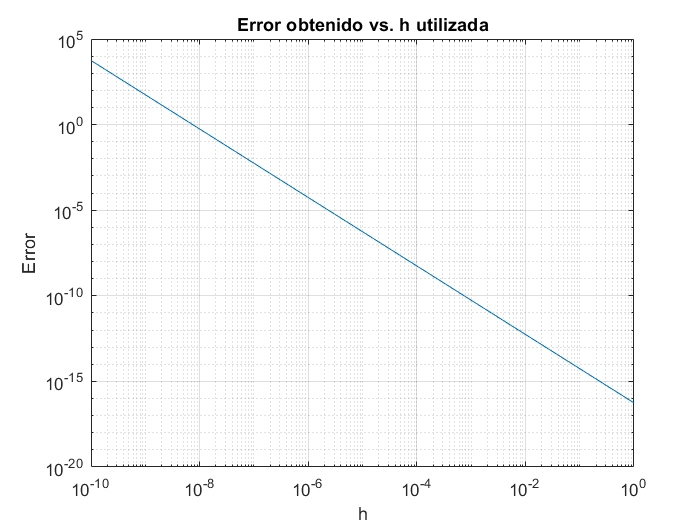

ddfForward2(f, x);

**Aproximación centrada de segundo orden:**

Segunda derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 0.00000000000000 	  0.0000000000000
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


ddfCentral(f, x);

### Aproximaciones de la función $f\left(\right)=2x^3 -\frac{\sqrt{\Pi }}{x}+2$ con `x = 1`

f = @( ) 2 * x.^3 - sqrt(pi) / x + 2;
x = 4;

#### Primera derivada

En este caso, aunque sí es una función derivable, no tiene argumentos de entrada; la derivación da como resultado` 0`, como si fuera una constante:

df = matlabFunction(diff(sym(f)))

df = function_handle with value:
    @()0.0


**Aproximación centrada de segundo orden:**

Como no es una práctica común que la función no tenga argumentos de entrada, se consideró esto como un error del usuario. Las funciones de la primera derivada lanzan un error al detectar esta situación, explicando claramente qué es lo que está mal con los paramentros recibidos:

dfCentral(f, x);

Error using ProyectoAlfaDinamita>firstDerCentral (line 217)
La función es una constante o no cuenta con argumentos de entrada.

Error in ProyectoAlfaDinamita>dfCentral (line 253)
    [hs, aprxs, err] = firstDerCentral(f, x, 1, 11);

#### Segunda derivada

De la misma manera que la primera derivada, la segunda también es igual a` 0`:

ddf = matlabFunction(diff(diff(sym(f))))

ddf = function_handle with value:
    @()0.0


**Aproximación centrada de segundo orden:**

Análogamente a los métodos de la primera derivada, las funciones de la segunda derivadalanzan el mensaje de error:

ddfCentral(f, x);

Error using ProyectoAlfaDinamita>secondDerCentral (line 499)
La función es una constante o no cuenta con argumentos de entrada.

Error in ProyectoAlfaDinamita>ddfCentral (line 536)
    [hs, aprxs, err] = secondDerCentral(f, x, 1, 11);

## Conclusiones

¿Qué fórmulas presentan menos errores? ¿Cómo dependen de `h`? ¿El error siempre disminuye si `h` se hace más pequeño? ¿Qué otro factor influye en el error?

## Referencias

[1] R. Fitzpatrick, «Numerical errors,» 29 Marzo 2006. [En línea]. Disponible en: http://farside.ph.utexas.edu/teaching/329/lectures/node33.html. [Último acceso: 25 Junio 2021].

[2] S. C. Chapra, «Total numerical error,» de *Applied Numerical Methods with MATLAB® for Engineers and Scientists*, Tercera ed., New York, McGraw-Hill, 2012, pp. 114-119.

[3] M. Mejía Olvera, «Computer Numbers: Fun with IEEE 754,» 17 Junio 2021. [En línea]. Disponible en: https://itam.instructure.com/courses/3332/assignments/40962?module_item_id=101786. [Último acceso: 25 Junio 2021].

## Anexo: Funciones

Se desarrollaron las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada; $O\left(h\right)$ y $O\left(h^2 \right)$. Es importante señalar que para las aproximaciones centradas, unicamente se presentan las correspondientes a $O\left(h^2 \right)$. Además, se implementaron métodos para imprimir los resultados obtenidos y desplegar la gráfica generada. Para cada función de aproximación, se codficó una versión más amigable al usuario que no regresa variables, sino que muestra dicha gráfica y valores calculados.

### Funciones auxiliares

function showResults(hs, aprxs, err)
% Imprime una tabla de las h generadas, su aproximación, y el error 
% correspondiente.
% Parámetros:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    format long
    res = [hs' aprxs' err']';
    fprintf('\t h \t     aproximación \t \t error\n');
    fprintf('%14.10f \t %16.14f \t %16.13f\n', res);
    format short
end


function plotError(hs, err)
% Despliega la gráfica correspondiente a las h generadas y sus errores 
% calculados, utiilizando la funcion loglog de MATLAB.
% Parámetros:
%    hs = las h utilizadas en las aproximaciones
%    err = los errores obtenidos

    loglog(hs, err)
    grid on
    title('Error obtenido vs. h utilizada')
    xlabel('h')
    ylabel('Error')
end

### Primera derivada

Para la primera derivada, se exponen las siguientes funciones:

- Aproximación hacia adelante: $O\left(h\right)$

- Aproximación hacia adelante: $O\left(h^2 \right)$

- Aproximación centrada: $O\left(h^2 \right)$

- Aproximación hacia atrás: $O\left(h\right)$

- Aproximación hacia atrás: $O\left(h^2 \right)$

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x+h\right)-f\left(x\right)}{h}$

function [hs, aprxs, err] = firstDerForwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h) de la primera
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - fx) / h;
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end



function dfForward1(f, x)
% Realiza la aproximación hacia adelante O(h) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerForwardOrder1(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia adelante O(h)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{-\frac{1}{2}f\left(x+2h\right)+2f\left(x+h\right)-\frac{3}{2}f\left(x\right)}{h}=\frac{-f\left(x+2h\right)+4f\left(x+h\right)-3f\left(x\right)}{2h}$

function [hs, aprxs, err] = firstDerForwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h^2) de la primera
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (-f(x + 2 * h) + 4 * f(x + h) - 3 * fx) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfForward2(f, x)
% Realiza la aproximación hacia adelante O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerForwardOrder2(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia adelante O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{1}{2}f\left(x+h\right)-\frac{1}{2}f\left(x-h\right)}{h}=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$

function [hs, aprxs, err] = firstDerCentral(f, x, h, n)
% Realiza n veces la aproximación centrada O(h^2) de la primera derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - f(x - h)) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfCentral(f, x)
% Realiza la aproximación centrada O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerCentral(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación centrada O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

#### Aproximación hacia atrás

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h}$

function [hs, aprxs, err] = firstDerBackwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia atrás O(h) de la primera derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (fx - f(x - h)) / h;
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfBackward1(f, x)
% Realiza la aproximación hacia atrás O(h) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerBackwardOrder1(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia atrás O(h)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{3}{2}f\left(x\right)-2f\left(x-h\right)+\frac{1}{2}f\left(x-2h\right)}{h}=\frac{3f\left(x\right)-4f\left(x-h\right)+f\left(x-2h\right)}{2h}$

function [hs, aprxs, err] = firstDerBackwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia atrás O(h^2) de la primera
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (3 * fx - 4 * f(x - h) + f(x - 2 * h)) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfBackward2(f, x)
% Realiza la aproximación hacia atrás O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerBackwardOrder2(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia atrás O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

### Segunda derivada

Para la segunda derivada, se exponen las siguientes funciones:

- Aproximación hacia adelante: $O\left(h\right)$

- Aproximación hacia adelante: $O\left(h^2 \right)$

- Aproximación centrada: $O\left(h^2 \right)$

Las aproximaciones hacia atrás no se codificaron debido a que están compuestas por las mismas fórmulas que las aproximaciones hacia adelante de su respecitvo orden.

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h\right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+2h\right)-2f\left(x+h\right)+f\left(x\right)}{h^2 }$

function [hs, aprxs, err] = secondDerForwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h) de la segunda
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + 2 * h) - 2 * f(x + h) + fx) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfForward1(f, x)
% Realiza la aproximación hacia adelante O(h) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = secondDerForwardOrder1(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación hacia adelante O(h)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{-f\left(x+3h\right)+4f\left(x+2h\right)-5f\left(x+h\right)+2f\left(x\right)}{h^2 }$

function [hs, aprxs, err] = secondDerForwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h^2) de la segunda
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (-f(x + 3 * h) + 4 * f(x + 2 * h) - 5 * f(x + h) + 2 * fx) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfForward2(f, x)
% Realiza la aproximación hacia adelante O(h^2) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = secondDerForwardOrder2(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación hacia adelante O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$

function [hs, aprxs, err] = secondDerCentral(f, x, h, n)
% Realiza n veces la aproximación centrada O(h^2) de la segunda derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - 2 * fx + f(x - h)) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfCentral(f, x)
% Realiza la aproximación centrada O(h^2) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = secondDerCentral(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación centrada O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end